# **Feature selection-based prediction of advanced fibrosis in HCV infected patients**

# Data Exploration

Load the dataset and pre-process the data.

load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29



% No missing values
sum(sum(ismissing(HCV)))

ans = 0


% Dealing only with two Stages - Advanced Fibrosis and Moderate Fibrosis
HCV.Baselinehistologicalstaging(HCV.Baselinehistologicalstaging<3)=0;
HCV.Baselinehistologicalstaging(HCV.Baselinehistologicalstaging>2)=1;

% Categorical to Binary
for i=[2,4:10]
    HCV.(i)(HCV.(i)==1)=0; %Absence
    HCV.(i)(HCV.(i)==2)=1; %Presence
end

% Create array of the data
HCV_array=table2array(HCV);

The dataset contains two data types - categorical and numeric respectively.

%Summary Statistics of continuous/numeric variables
cont_array=HCV_array(:,[1,3,11:27])

cont_array =           56          35        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5
          46          29       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085
          57          33        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829
          49          33        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301
          59          32        3661     4606375          11      18768

mean_val = mean(cont_array);
std_val= std(cont_array);
median_val = median(cont_array);
min_val = min(cont_array);
max_val = max(cont_array);
range_val = range(cont_array);
[corr_val, p_val] = corr(cont_array,HCV_array(:,29),'type','Spearman');
summary_table1 = sortrows(array2table([mean_val;std_val;median_val;min_val;max_val;range_val;corr_val';p_val']', ...
    'VariableNames',{'mean','stddev','median','min','max','range','Spearman_Correlation_Coefficient','P-value'}, ...
    'RowNames',HCV.Properties.VariableNames([1,3,11:27])),'Spearman_Correlation_Coefficient','descend','ComparisonMethod','abs')

summary_table1 = 19×8 table
                      mean         stddev        median       min        max          range       Spearman_Correlation_Coefficient     P-value 
                   __________    __________    __________    _____    __________    __________    ________________________________    _________

    BMI                28.609        4.0762            29       22            35            13                -0.070331               0.0088368
    RNAEF          2.9138e+05     2.677e+05    2.4405e+05        5    8.1033e+05    8.1033e+05                 0.051722                0.054302
    ALTafter24w        33.438        7.0736            34        5      

% Top 8 rank correlated numeric features 
head(summary_table1)

ans = 8×8 table
                      mean         stddev        median      min       max          range       Spearman_Correlation_Coefficient     P-value 
                   __________    __________    __________    ___    __________    __________    ________________________________    _________

    BMI                28.609        4.0762            29    22             35            13               -0.070331                0.0088368
    RNAEF          2.9138e+05     2.677e+05    2.4405e+05     5     8.1033e+05    8.1033e+05                0.051722                 0.054302
    ALTafter24w        33.438        7.0736            34     5             45            40

% Summary Statistics for categorical variables
categorical_dat=HCV(:,[2,4:10]);
cat = HCV_array(:,[2,4:10]);
prevalent_val = mode(cat);
count_val = countcats(categorical(cat),1);
perc_val = count_val/length(cat);
%Chi-square Statistic
chi2=zeros(8,1);
p=zeros(8,1);
for i=1:8
    [~,chi2(i),p(i)] = crosstab(categorical_dat.(i),HCV.Baselinehistologicalstaging);
end
summary_table2 = sortrows(array2table([prevalent_val',count_val',perc_val'*100,chi2,p],"RowNames",HCV.Properties.VariableNames([2,4:10]),'VariableNames',{'Mode','Count_Absent','Count_Present','Percent_Absent','Precent_Present','Chi_Square-statistic','P-value'}),'P-value')

summary_table2 = 8×7 table
                                  Mode    Count_Absent    Count_Present    Percent_Absent    Precent_Present    Chi_Square-statistic    P-value 
                                  ____    ____________    _____________    ______________    _______________    ____________________    ________

    NauseaVomting                  1          689              696             49.747            50.253                  4.9507          0.02608
    Epigastricpain                 1          687              698             49.603            50.397                  3.0912         0.078715
    Gender                         0          707              678             51.047            48.953

# DATA VISUALIZATION

Binary Data

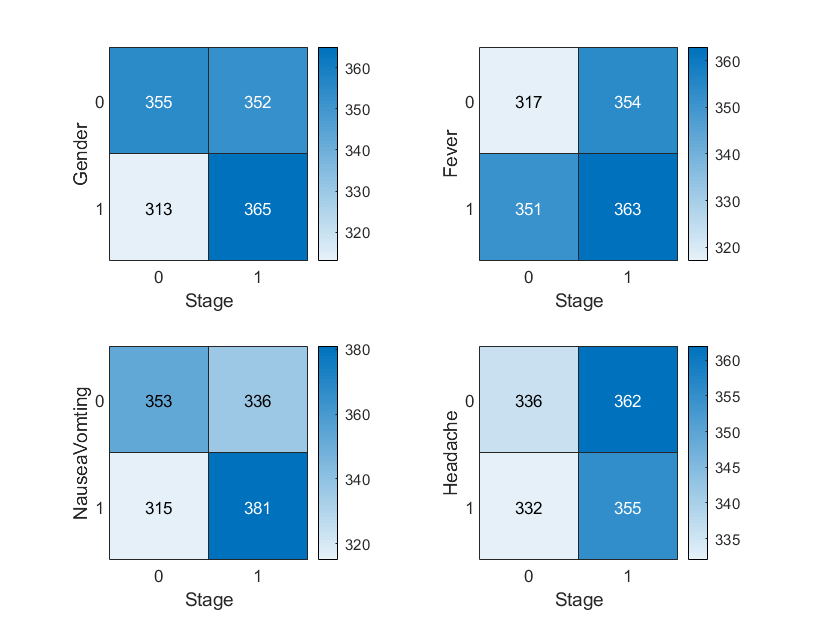

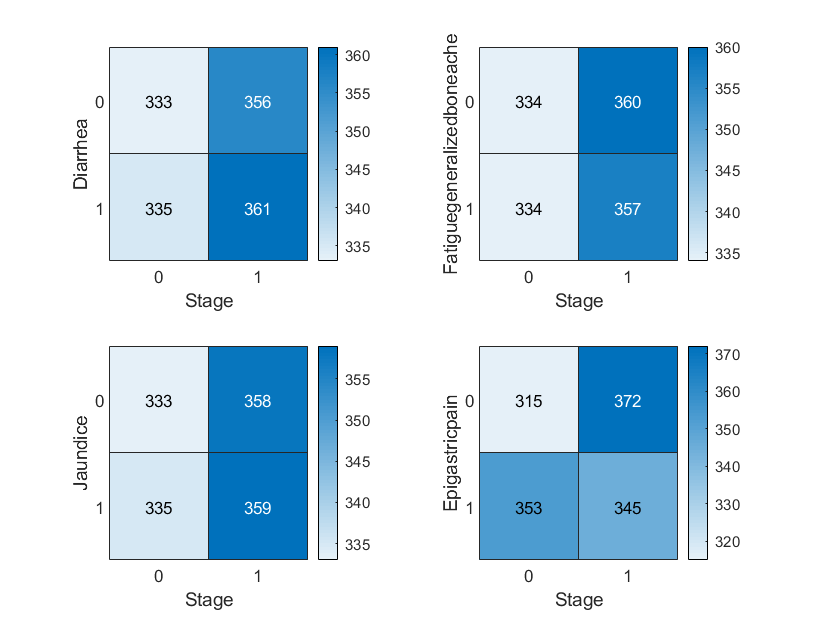

k=1;
m=1;
for i=[2,4:10]
    figure(m)
    subplot(2,2,k)
    h=heatmap(HCV,'Baselinehistologicalstaging',HCV.Properties.VariableNames(i));
    h.Title={''};
    h.XLabel={'Stage'};
    k=k+1;
    if k>4
        m=m+1;
        k=1;
    end
end

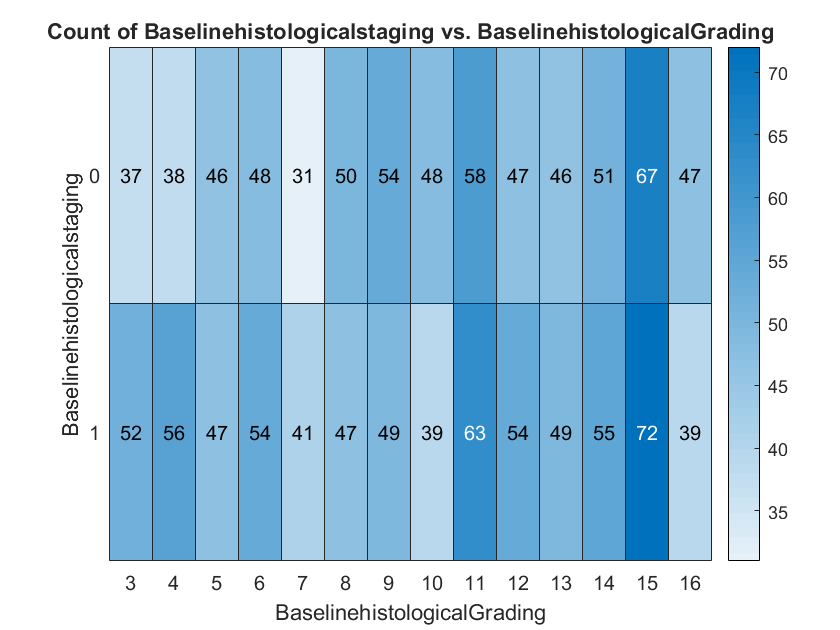

figure()
h=heatmap(HCV,'BaselinehistologicalGrading','Baselinehistologicalstaging');

Continuous Data

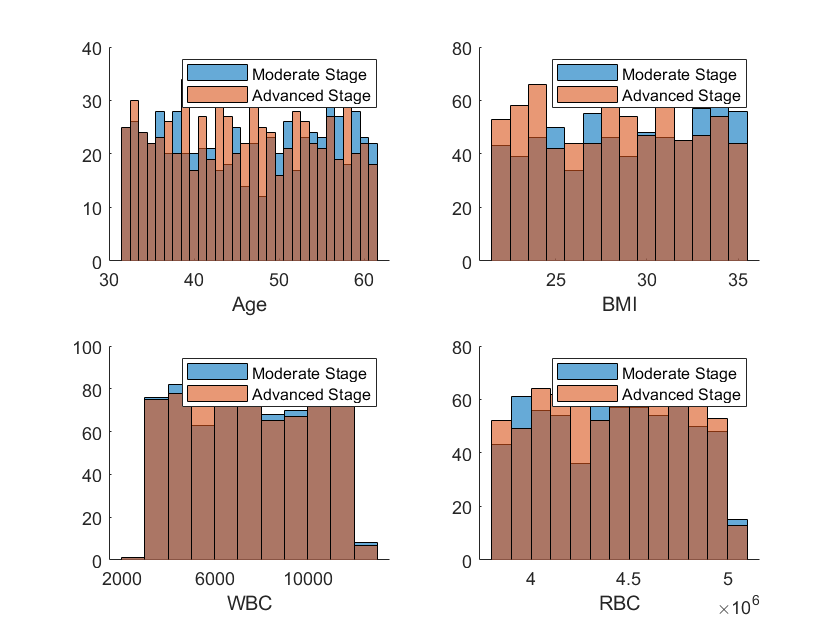

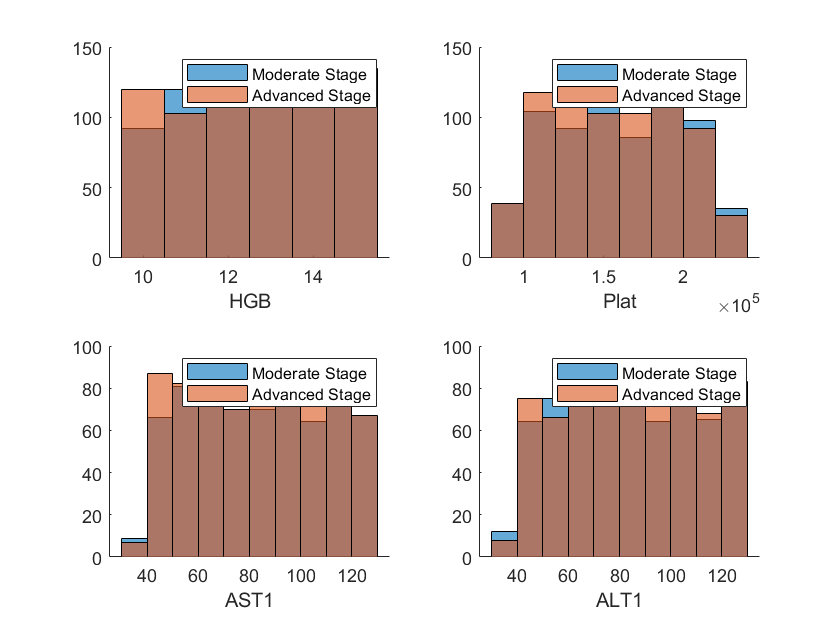

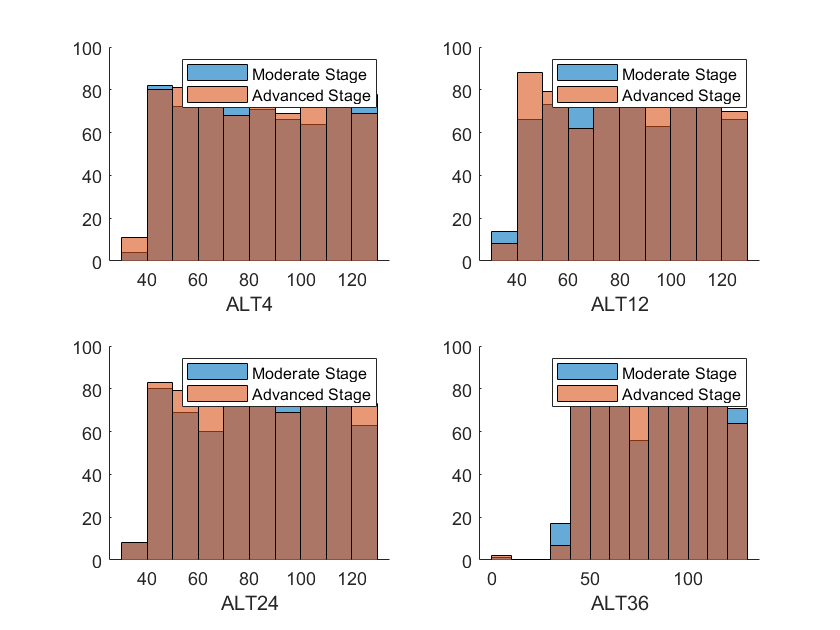

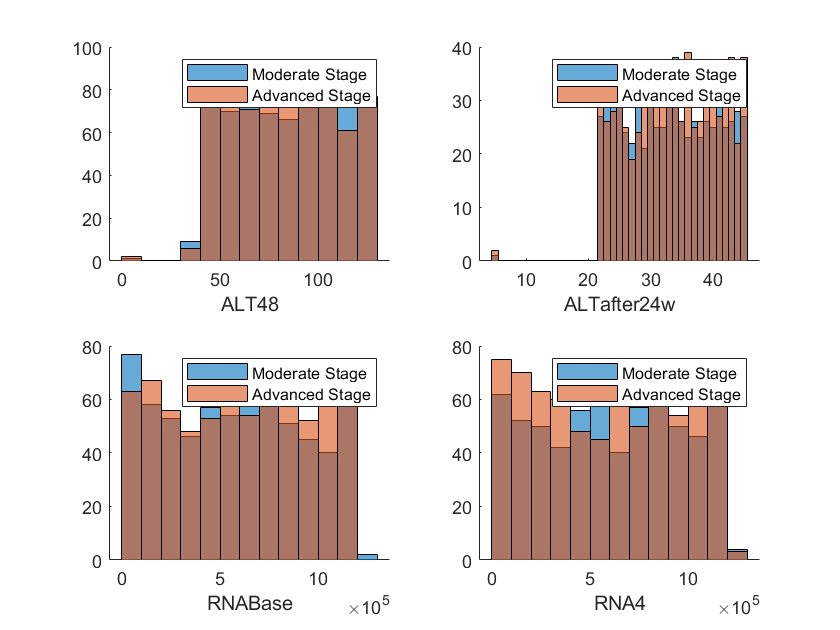

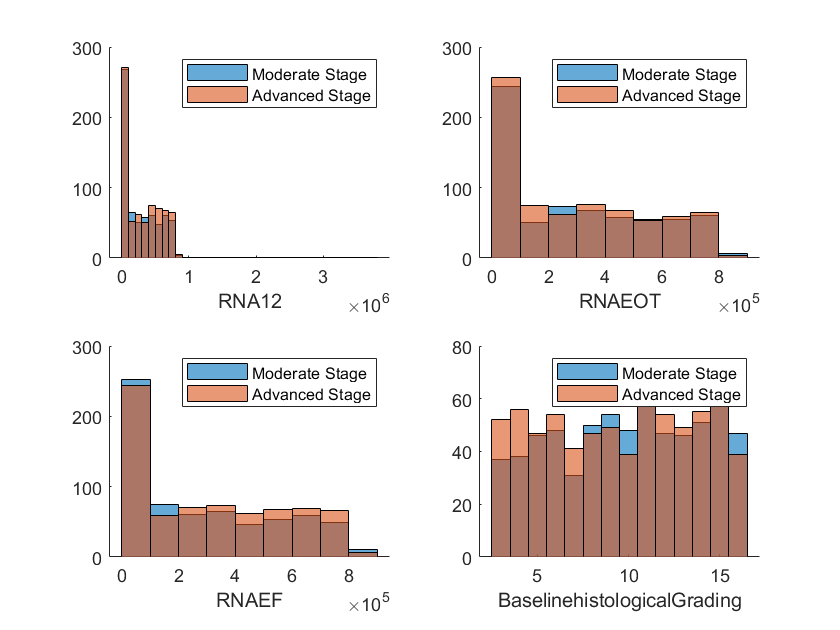

m=4;
for i=[1,3,11:28]
    figure(m)
    subplot(2,2,k)
    hold on
    histogram(HCV.(i)(HCV.(29)==0))
    histogram(HCV.(i)(HCV.(29)==1))
    xlabel(HCV.Properties.VariableNames(i));
    legend({'Moderate Stage','Advanced Stage'})
    hold off
    k=k+1;
    if k>4
        m=m+1;
        k=1;
    end
end

## Biological Significance

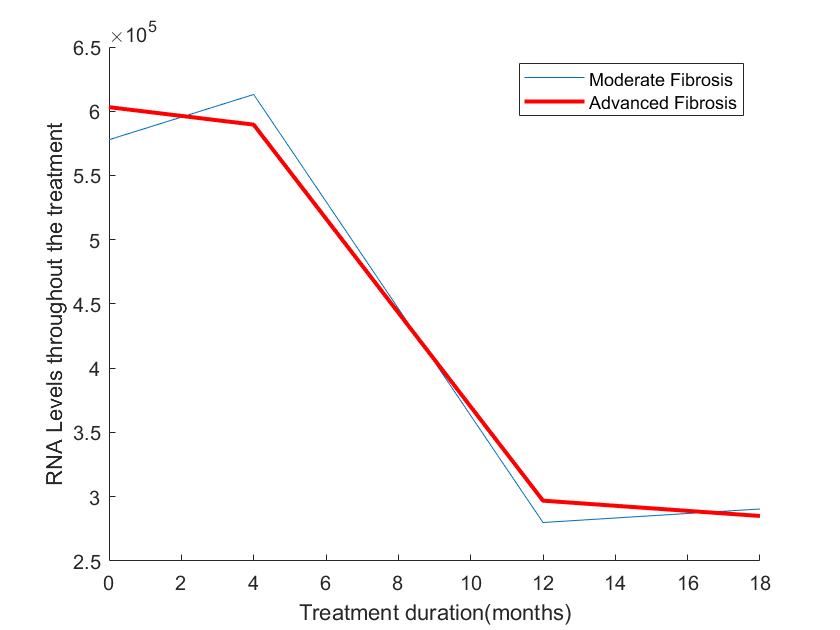

% Observe RNA levels and ALT levels for moderate and advanced fibrosis
moderateFib=HCV(HCV.Baselinehistologicalstaging==0,:);
advancedFib=HCV(HCV.Baselinehistologicalstaging==1,:);
mod=table2array(moderateFib);
adv=table2array(advancedFib);

figure();
hold on
plot([0,4,12,18],mean(mod(:,23:26)))
ylabel('RNA Levels throughout the treatment','LineWidth',2,'LineStyle',"--")
xlabel('Treatment duration(months)')
plot([0,4,12,18],mean(adv(:,23:26)),'Color','r','LineWidth',2)
legend('Moderate Fibrosis','Advanced Fibrosis')
hold off

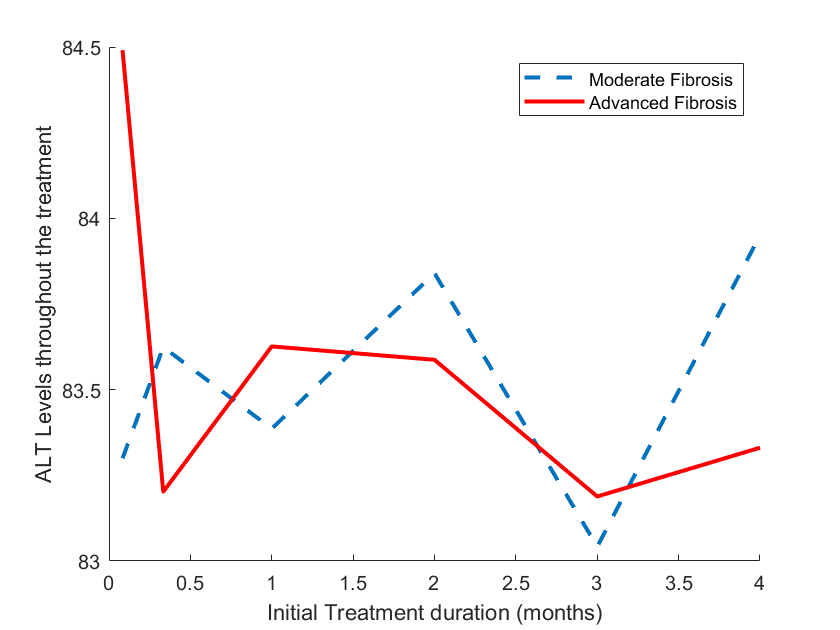

%230th individual ideal case

figure();
hold on
plot([1,4,12,24,36,48]/12,mean(mod(:,16:21)),'LineWidth',2,'LineStyle',"--" )
ylabel('ALT Levels throughout the treatment')
xlabel('Initial Treatment duration (months)')
plot([1,4,12,24,36,48]/12,mean(adv(:,16:21)),'Color','r','LineWidth',2)
legend('Moderate Fibrosis','Advanced Fibrosis')
hold off

%445th individual ideal case

We see that there is a drastic difference between the ALT levels of individuals with moderate fibrosis and those with advanced fibrosis while the RNA levels are close by. The surprising thing is that for both the groups the ALT levels fall lowest at the 3rd month and start rising up again. I believe the ALT levels keep fluctuating and slowly come to a constant by the end of treatment which is the 18th month.

## Min-max normalization of data

X=HCV_array(:,1:28);
colmin = min(X); colmax = max(X);
X = rescale(X, 'InputMin', colmin, 'InputMax', colmax);
Y=HCV_array(:,29);
HCV_new=array2table([X,Y],"VariableNames",HCV.Properties.VariableNames)

HCV_new = 1385×29 table
      Age       Gender      BMI       Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain      WBC         RBC       HGB      Plat        AST1       ALT1       ALT4       ALT12      ALT24       ALT36      ALT48     ALTafter24w    RNABase       RNA4       RNA12       RNAEOT      RNAEF      BaselinehistologicalGrading    Baselinehistologicalstaging
    ________    ______    ________

# FEATURE SELECTION

## Method 0 : TTests

for i=1:28
    [h0(i),p0(i)]=ttest2(HCV_new.(i)(HCV_new.Baselinehistologicalstaging==0),HCV_new.(i)(HCV_new.Baselinehistologicalstaging==1));
end
sortrows(array2table([h0',p0'],'RowNames',HCV_new.Properties.VariableNames(1:28),'VariableNames',{'Significant/Non-significant','P-value'}),'P-value')

ans = 28×2 table
                                   Significant/Non-significant     P-value 
                                   ___________________________    _________

    BMI                                         1                 0.0091578
    NauseaVomting                               1                  0.026081
    RNAEF                                       1                  0.039441
    Epigastricpain                              0                  0.078818
    BaselinehistologicalGrading                 0                   0.12714
    Gender                                      0                   0.13207
    ALTafter24w                                 0                   0.16479
    RNABase                                     0                   0.18344
    RNA4  

A p-value of 0.0092,0.0261 and 0.0394 against significance level of 0.05 means that the two groups can be differentiated and that the variable is significant. Thus, according to the ttest BMI, NauseaVomting and RNAEF are significant variables.

%Correlated data
HCV_test=array2table([HCV_new.BMI, HCV_new.RNAEF, HCV_new.NauseaVomting, HCV_new.Baselinehistologicalstaging],'VariableNames',{'BMI','RNAEF','NauseaVomting','Stage'});

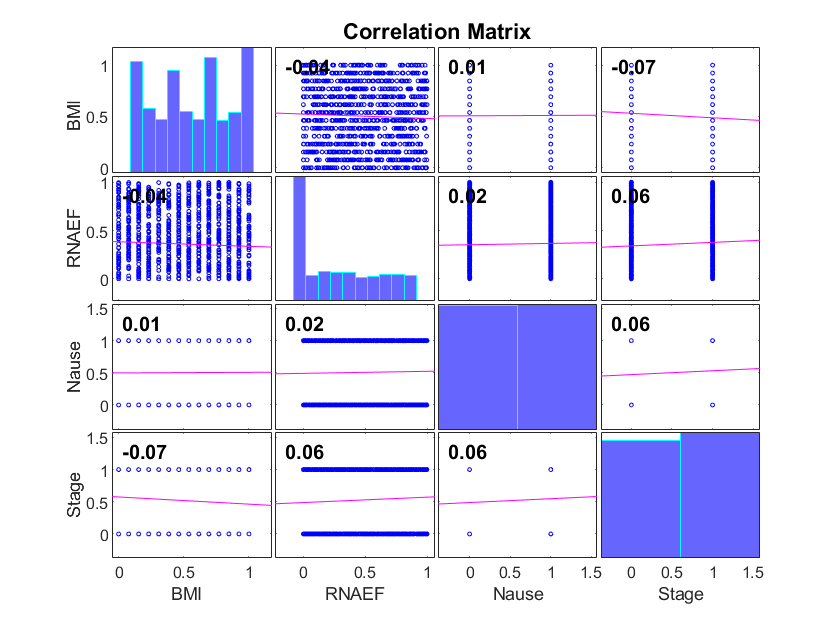

corrplot(HCV_test)

The low correlation value can be explained by the slopes of least-squares reference lines.

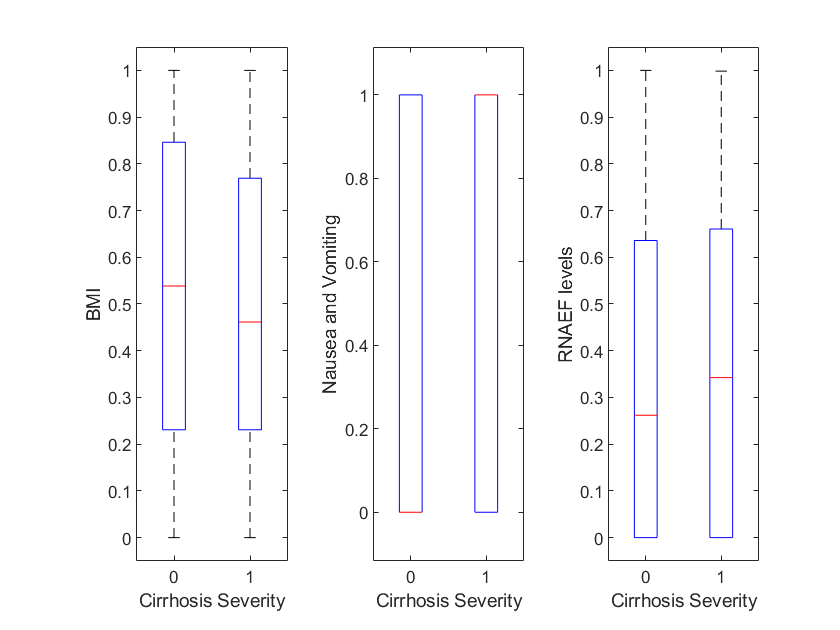

% Boxplots of significant variables
figure()
subplot(1,3,1)
boxplot(HCV_test.BMI,HCV_test.Stage)
ylabel('BMI')
xlabel('Cirrhosis Severity')
subplot(1,3,2)
boxplot(HCV_test.NauseaVomting,HCV_test.Stage)
ylabel('Nausea and Vomiting')
xlabel('Cirrhosis Severity')
subplot(1,3,3)
boxplot(HCV_test.RNAEF,HCV_test.Stage)
ylabel('RNAEF levels')
xlabel('Cirrhosis Severity')

## METHOD 1 

The data has continuous([1,3,11:27]) as well as ordinal data([2,4:10,28,29]) and so on refering [https://medium.com/@outside2SDs/an-overview-of-correlation-measures-between-categorical-and-continuous-variables-4c7f85610365,](https://medium.com/@outside2SDs/an-overview-of-correlation-measures-between-categorical-and-continuous-variables-4c7f85610365,)

We use **bias corrected Cramer’s V **(derived from Chi-Square) to measure association between categorical variables, ** logistic regression** to understand association between categorical and continuous variable pairs and rank-based correlation metrics such as **Spearman** to understand association between continuous variables.

Note : Catagorical data doesn't come from normal distribution and hence, as the output is categorical we cannot use linear regression (assumes normality) 

#### Association between categorical-categorical variables

categorical_dat=HCV_new(:,[2,4:10,28]);

Categorical variables with 2 levels

chi2=zeros(8,1);
p1=zeros(8,1);
for i=1:8
    [~,chi2(i),p1(i)] = crosstab(categorical_dat.(i),HCV_new.Baselinehistologicalstaging);
end

chi-square statistics is sensitive to sample size and so bias corrected cramer's V is preferred

For 2x2 contingency table , bias corrected cramer's V=phi-coefficient

bias_cramerV=sqrt(chi2/height(HCV));

Categorical variable with more than 2 levels

Baselinehistologicalgrading is a categorical variable which needs to be tested for it's strength of association. For 14x2 contingency table,

[tbl1,chi2(9,1),p1(9,1)] = crosstab(HCV_new.BaselinehistologicalGrading,HCV_new.Baselinehistologicalstaging);
%For bias corrected cramer's V
tbl1_size=size(tbl1);
bias_cramerV(9,1)=sqrt(max([0,(chi2(9,1)/1385)-((tbl1_size(1)-1)*(tbl1_size(2)-1))/(height(HCV)-1)])/min([tbl1_size(2)-((tbl1_size(2)-1)^2)/(height(HCV)-1),tbl1_size(1)-((tbl1_size(1)-1)^2)/(height(HCV)-1)]));

Association of categorical variables with Stages is as follows -

categorical_summary=sortrows(array2table([chi2,p1,bias_cramerV],"RowNames",categorical_dat.Properties.VariableNames,'VariableNames',{'Chi-Square Statistic','P-value','CramersV_Strength'}),'P-value','ascend')

categorical_summary = 9×3 table
                                   Chi-Square Statistic    P-value     CramersV_Strength
                                   ____________________    ________    _________________

    NauseaVomting                           4.9507          0.02608         0.059787    
    Epigastricpain                          3.0912         0.078715         0.047243    
    Gender                                  2.2702          0.13188         0.040486    
    Fever                                  0.50898          0.47558          0.01917    
    BaselinehistologicalGrading             9.1334           0.7628                0    
    Fatiguegeneralizedboneache           0.0060541          0.93798        0.0020907    
    Diarrhea                      

On observing the above table, we see that according to strength of association (given by cramer's V coefficient) and p-value, if significance level 5% is considered, only NauseaVomiting seems to be a significant variable.

#### Association between categorical-continuous variables

continuous_var=HCV_new(:,[1,3,11:27]);
[B,dev,stats]=mnrfit(X(:,[1,3,11:27]),categorical(Y))

B =    -0.1123
    0.1901
    0.4397
   -0.1000
    0.0302
   -0.0278
    0.1407
    0.1238
   -0.1801
    0.0364


dev = 1.8968e+03

stats = struct with fields:
         beta: [20×1 double]
          dfe: 1365
         sfit: 1.0073
            s: 1
      estdisp: 0
         covb: [20×20 double]
    coeffcorr: [20×20 double]
           se: [20×1 double]
            t: [20×1 double]
            p: [20×1 double]
        resid: [1385×2 double]
       residp: [1385×2 double]
       residd: [1385×1 double]


ans =     0.8131
    0.2905
    0.0118
    0.5908
    0.8733
    0.8613
    0.4535
    0.5060
    0.3375
    0.8423


sortrows(array2table([B(2:end),stats.p(2:end)],"RowNames",continuous_var.Properties.VariableNames,'VariableNames',{'B-value','P-value'}),'P-value','ascend')

ans = 19×2 table
                    B-value     P-value 
                   _________    ________

    BMI              0.43971    0.011765
    RNAEF           -0.38827    0.044532
    RNAEOT            0.3169     0.10258
    ALTafter24w     -0.41988     0.17322
    RNABase         -0.23097     0.21194
    RNA4             0.19322     0.28558
    Age              0.19007      0.2905
    ALT1            -0.18008     0.33747
    RNA12           -0.66556     0.41575
    Plat             0.14075     0.45352
    AST1             0.12381       0.506
    ALT48            0.16314     0.52538
    WBC             -0.10003     0.59085
    ALT24           0.045222     0.80746
    ALT4    

Here at 5% significance level, BMI followed by RNAEF are most significant.

### Thus, NauseaVomiting, BMI and RNAEF are significant variables. Similar to Method 0.

## METHOD 2

Only one method can be used for both types of features using embedded type feature selection. For this particular function when we give input as a table it assumes last column to be response variable and  treats all categorical or logical variables as categorical.

[https://www.mathworks.com/help/stats/feature-selection.html](https://www.mathworks.com/help/stats/feature-selection.html)

### Embedded Type Feature Selection

stepwiseglm(HCV)

1. Adding BMI, Deviance = 344.1219, FStat = 6.810953, PValue = 0.009157848
2. Adding NauseaVomting, Deviance = 342.8689, FStat = 5.050527, PValue = 0.02477567


ans = Generalized linear regression model:
    Baselinehistologicalstaging ~ 1 + BMI + NauseaVomting
    Distribution = Normal

Estimated Coefficients:
                      Estimate        SE         tStat       pValue  
                     __________    _________    _______    __________

    (Intercept)         0.73428      0.09579     7.6655    3.3388e-14
    BMI              -0.0086275    0.0032847    -2.6266     0.0087198
    NauseaVomting      0.060158     0.026769     2.2473      0.024776


1385 observations, 1382 error degrees of freedom
Estimated Dispersion: 0.248
F-statistic vs. constant model: 5.94, p-value = 0.0027

### Thus, BMI and NauseaVomiting only are sigificant variables.

## METHOD 3

mdls=fitglm(HCV_new,'link','logit','Distribution',"binomial")

mdls = Generalized linear regression model:
    logit(Baselinehistologicalstaging) ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT12 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF + BaselinehistologicalGrading
    Distribution = Binomial

Estimated Coefficients:
                                    Estimate        SE         tStat       pValue  
                                   __________    ________    _________    _________

    (Intercept)                       0.35215     0.52294       0.6734      0.50069
    Age                               -0.1998     0.18133      -1.1019      0.27052
    Gender                            0.18327   

Generally we start with deleting the variables with highest p-value

new=HCV_new;
while mdls.devianceTest.pValue(2)>0.05
    [b3,i3]=maxk(mdls.Coefficients.pValue,1);
    sprintf('Variable removed :%s',string(new.Properties.VariableNames(i-1)))
    new.(i3-1)=[];
    mdls=fitglm(new,'link','logit','Distribution',"binomial");
end

ans = 'Variable removed :Diarrhea'

ans = 'Variable removed :ALT36'

ans = 'Variable removed :Headache'

ans = 'Variable removed :HGB'

ans = 'Variable removed :ALT12'

mdls.devianceTest.pValue(2)

ans = 0.0387

fitglm(new)

ans = Generalized linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + Plat + AST1 + ALT1 + ALT4 + ALT24 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF + BaselinehistologicalGrading
    Distribution = Normal

Estimated Coefficients:
                                    Estimate        SE        tStat        pValue  
                                   __________    ________    ________    __________

    (Intercept)                       0.59542     0.11498      5.1785    2.5724e-07
    Age                             -0.048631    0.044394     -1.0955       0.27351
    Gender                           0.044787    0.026915       1.664      0.096339
    BMI   

Here, we realise that all other methods look at every feature individually but this, looks at them as a whole and makes a linear model of those and the determines the p-value of the model. 

## METHOD 4

The Kruskal-Wallis Test has been used for continuous variables with non-normal distribution. The Chi-square test has been used for categorical variables. Pearson correlation coefficients between fibrosis and each variable have been assessed. [https://ieeexplore-ieee-org.proxy.lib.umich.edu/document/7891989](https://ieeexplore-ieee-org.proxy.lib.umich.edu/document/7891989)

for i=[1,3,11:28]
    p41(i)=kruskalwallis(HCV_new.(i),HCV_new.Baselinehistologicalstaging,"off");
end
for i=[2,4:10]
    [~,~,p41(i)] = crosstab(HCV_new.(i),HCV_new.Baselinehistologicalstaging);
end
[r1,p42]=corr(X,Y,'type',"Pearson")

r1 =    -0.0247
    0.0405
   -0.0700
   -0.0192
    0.0598
   -0.0019
    0.0020
   -0.0021
   -0.0008
   -0.0472


p42 =     0.3591
    0.1321
    0.0092
    0.4759
    0.0261
    0.9441
    0.9411
    0.9380
    0.9763
    0.0788


sortrows(array2table([p41',r1,p42],'RowNames',HCV.Properties.VariableNames(1:28),'VariableNames',{'P-value','Pearsons_Coeff','Pearsons_P-value'}),'P-value')

ans = 28×3 table
                                    P-value     Pearsons_Coeff    Pearsons_P-value
                                   _________    ______________    ________________

    BMI                            0.0088842      -0.070005          0.0091578    
    NauseaVomting                    0.02608       0.059787           0.026081    
    RNAEF                           0.054333       0.055349           0.039441    
    Epigastricpain                  0.078715      -0.047243           0.078818    
    Gender                           0.13188       0.040486            0.13207    
    BaselinehistologicalGrading       0.1379       -0.04101            0.12714    
    ALTafter24w                      0.14186       0.037347            0.16479    
    RN

As the p-value increases, the strength of correlation given by Pearson's coefficient decreases. For significance level of 0.05, **BMI, NauseaVomting and RNAEF** are significant again just like method 1 for Pearson's correlation while BMI and NauseaVomting are significant like method 2.

## METHOD 5

Unsupervised Learning - PCA

Xpca=zscore((HCV_array-min(HCV_array))./(max(HCV_array)-min(HCV_array)));
ExpectedOutput=table2array(HCV_new(:,29));
[coeff,score,latent,~,explained]=pca(Xpca)

coeff =    -0.0445   -0.0331   -0.1547   -0.1982   -0.1955    0.0982   -0.1319   -0.1184   -0.2385   -0.0265    0.0644    0.3006    0.5806    0.1130    0.0612   -0.0897    0.2583   -0.0894   -0.1774   -0.1875   -0.1684    0.2457   -0.1664    0.1906   -0.1040    0.0157    0.1668   -0.0831   -0.0289
   -0.0069   -0.0093   -0.0289    0.0738    0.2578    0.1900    0.2896    0.0796   -0.3043    0.3899   -0.0790    0.3485   -0.0788   -0.1738    0.0304   -0.0007   -0.2697    0.1679    0.0554   -0.2674    0.0435    0.1963   -0.3018   -0.2321    0.0825   -0.0792    0.0495    0.1051    0.0610
   -0.0614   -0.0124    0.2295    0.4466   -0.2109   -0.1458   -0.1181   -0.0580   -0.1594    0.0366   -0.1910    0.0988   -0.0059    0.0442    0.2867    0.2187   -0.1550    0.2557    0.0180    0.0683   -0.1942   -0.1781   -0.1713    0.2143   -0.1471    0.4325    0.0796   -0.0387    0.0144
    0.0187   -0.0003   -0.1485    0.1059    0.0245   -0.0969   -0.1100    0.4491   -0.0373    0.3947    0.1097   -0.135

score =    -1.8028   -1.3862    2.4746    0.7122    0.1476   -1.5091   -1.6015    0.2543   -3.6699   -0.7729    2.1479   -1.0909   -0.0221   -1.7456   -0.0120   -0.5084    0.2455   -2.1750   -0.5932    0.2340    0.5765   -0.3133   -0.4243    1.5533   -1.7405    0.4974    1.7108    0.4960   -0.3551
    0.0844    0.0015   -0.5168   -0.3531   -0.6223   -1.2432   -0.2816    0.3392   -0.8735   -1.6623   -0.1674    0.6442    0.2792    1.2687   -0.1586   -0.3635    0.4801    2.3060    2.0581    0.7802   -2.1000   -1.0551    0.9003   -0.1619    0.8951   -1.9566   -0.5442    0.8371   -0.7297
    0.5870    2.6263    2.5980   -1.2570   -2.2253   -1.2445   -1.2880    0.2439   -2.6348    1.1011    1.0349   -1.4355    0.7275   -1.5158   -1.7761   -0.7284   -0.9059   -1.1954   -1.5401    1.5609    0.3400   -0.4237   -1.6903    0.7462   -0.0081    0.8451    1.6401   -2.0231   -0.5049
    2.1241    1.0550    0.0474   -0.7747   -1.8014    1.3647    1.9753   -0.2040   -0.6977    0.0585    0.2641   -0.067

latent =     1.8974
    1.2473
    1.2360
    1.1929
    1.1630
    1.1430
    1.1291
    1.1069
    1.0609
    1.0553


explained =     6.5429
    4.3012
    4.2622
    4.1136
    4.0104
    3.9413
    3.8934
    3.8169
    3.6582
    3.6390


b=bar(explained(1:15))

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15]
        YData: [6.5429 4.3012 4.2622 4.1136 4.0104 3.9413 3.8934 3.8169 3.6582 3.6390 3.5928 3.5524 3.5298 3.4826 3.4101]

  Show all properties


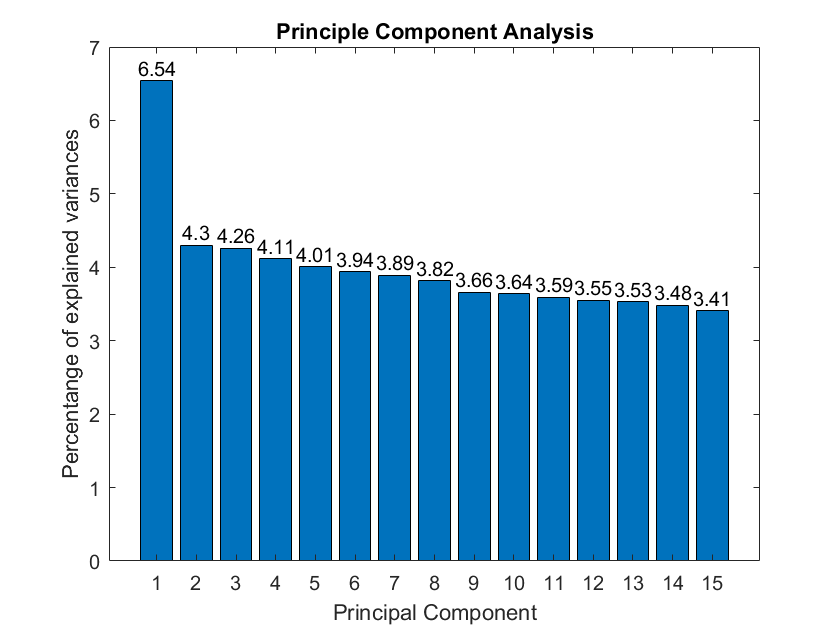

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,2));
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xlabel('Principal Component')
ylabel('Percentange of explained variances')
title('Principle Component Analysis')

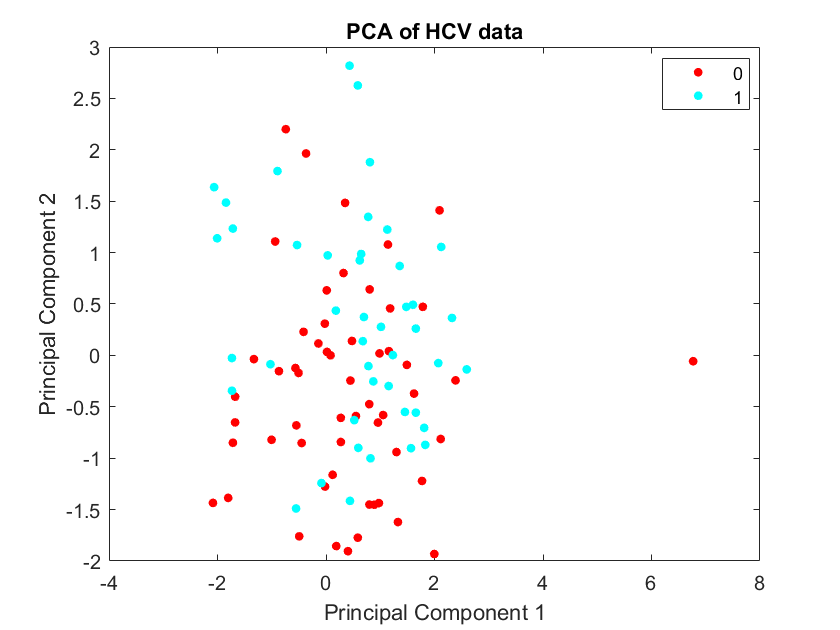

figure
gscatter(score(1:100,1), score(1:100,2), ExpectedOutput(1:100,1))
xlabel('Principal Component 1')
ylabel('Principal Component 2')
title('PCA of HCV data')

sortrows(array2table([coeff(:,1),coeff(:,2),coeff(:,3),coeff(:,4)],'RowNames',HCV_new.Properties.VariableNames(1:29),'VariableNames',{'PC1','PC2','PC3','PC4'}),'PC1','descend')

ans = 29×4 table
                                     PC1           PC2           PC3           PC4    
                                   ________    ___________    __________    __________

    RNAEF                           0.57084      -0.011418      0.041143    -0.0047114
    RNAEOT                          0.56282      -0.043871      0.072362       0.03918
    RNA12                           0.55178      -0.010067      0.030964      0.045738
    Epigastricpain                 0.090461       -0.31275     -0.088965       0.14075
    Jaundice                       0.060201      -0.054506      -0.15397      -0.25005
    ALT36                          0.055159        0.10195      -0.08942      -0.13695
    Baselinehistologicalstaging

%For threshold 0.1050
PC12=mean(abs(coeff(:,1:2)),2);
sortrows(table(PC12,'Rownames',HCV_new.Properties.VariableNames),'PC12','descend')

ans = 29×1 table
                                     PC12  
                                   ________

    RNAEOT                          0.30335
    RNAEF                           0.29113
    RNA12                           0.28092
    NauseaVomting                   0.27173
    Plat                            0.21606
    Epigastricpain                  0.20161
    WBC                              0.1508
    RBC                             0.14608
    ALT1                             0.1423
    ALT48                           0.13524
    Baselinehistologicalstaging     0.12718
    RNA4                              0.123
    ALT24                           0.11001
    ALT12                           0.10336
    <s

PC14=mean(abs(coeff(:,1:4)),2);
sortrows(table(PC14,'Rownames',HCV_new.Properties.VariableNames),'PC14','descend')

ans = 29×1 table
                                    PC14  
                                   _______

    ALT1                           0.23404
    ALT24                          0.20012
    BMI                            0.18749
    ALT12                           0.1862
    Plat                           0.18087
    RNAEOT                         0.17956
    ALT48                          0.16785
    RNA12                          0.15964
    Epigastricpain                 0.15823
    RNAEF                          0.15703
    NauseaVomting                  0.14785
    Baselinehistologicalstaging    0.14676
    HGB                             0.1446
    Diarrhea                         0.143
    Headache  


%Variables removed by thresholding PC1-PC2 interaction
X4=HCV_new;
del1=X4.Properties.VariableNames(find(PC12<0.1050)')

del1 = 1×16 cell array
    {'Age'}    {'Gender'}    {'BMI'}    {'Fever'}    {'Headache'}    {'Diarrhea'}    {'Fatiguegeneralizedboneache'}    {'Jaundice'}    {'HGB'}    {'AST1'}    {'ALT4'}    {'ALT12'}    {'ALT36'}    {'ALTafter24w'}    {'RNABase'}    {'BaselinehistologicalGrading'}


X4=removevars(X4,del1)

X4 = 1385×13 table
    NauseaVomting    Epigastricpain      WBC         RBC         Plat       ALT1       ALT24       ALT48       RNA4       RNA12       RNAEOT      RNAEF      Baselinehistologicalstaging
    _____________    ______________    ________    ________    ________    _______    ________    _______    ________    ________    ________    ________    ___________________________

          0                1            0.48672     0.35971     0.14327    0.50562     0.47191          0     0.52802    0.077231           0           0               

X4=table2array(X4);
%Variables removed by thresholding PC1-PC4 interaction
X5=HCV_new;
del2=X5.Properties.VariableNames(find(PC14<0.1050)')

del2 = 1×7 cell array
    {'Gender'}    {'Fever'}    {'Fatiguegeneralizedboneache'}    {'AST1'}    {'ALT36'}    {'ALTafter24w'}    {'BaselinehistologicalGrading'}


X5=removevars(X5,del2)

X5 = 1385×22 table
      Age         BMI       NauseaVomting    Headache    Diarrhea    Jaundice    Epigastricpain      WBC         RBC       HGB      Plat       ALT1       ALT4       ALT12      ALT24       ALT48     RNABase       RNA4       RNA12       RNAEOT      RNAEF      Baselinehistologicalstaging
    ________    ________    _____________    ________    ________    ________    ______________    ________    ________    ___    ________

X5=table2array(X5);

**Thus, the efficiency of models with distinct features selected by method 1, 2, 3 and 5 will be determined.**

# SUPERVISED LEARNING

## TRAINING SUPERVISED LEARNING MODEL (Categorical Variables can be specified)

The problem here is classification based so we use logistic regression and not linear regression.

## Using Method 1 of feature selection

%Method 1
X1=[HCV_new.BMI, HCV_new.NauseaVomting, HCV_new.RNAEF];
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(X1,Y,0.7);

### Why new classification models?

There is point implementing new methods only if they improve the classification results.

%Logistic Regression
tic
Logmodel=fitglm(Xtrain1,categorical(Ytrain1),'link','logit','Distribution',"binomial",'CategoricalVars',{'x2'});
pred1=predict(Logmodel,Xtest1);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
[accuracy1,precision1,recall1]=meas(categorical(pred1),Ytest1);
toc

Elapsed time is 0.076980 seconds.


    
%Random Forest (Classification)
tic
RFmodel=TreeBagger(100,Xtrain1,categorical(Ytrain1),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[2]);
pred2=categorical(predict(RFmodel,Xtest1));
[accuracy2,precision2,recall2]=meas(pred2,Ytest1);
toc

Elapsed time is 2.735312 seconds.


    
%Decision Tree (Classification)
tic
DecisionTree=fitctree(Xtrain1,categorical(Ytrain1),"CategoricalPredictors",[2]);
pred3=predict(DecisionTree,Xtest1);
[accuracy3,precision3,recall3]=meas(pred3,Ytest1);
toc

Elapsed time is 0.062668 seconds.



%Naive Bayes Method
tic
NBmodel=fitcnb(Xtrain1,categorical(Ytrain1),'PredictorNames',{'BMI','NauseaVomiting','RNAEF'},"CategoricalPredictors",'NauseaVomiting');
pred4=predict(NBmodel,Xtest1);
[accuracy4,precision4,recall4]=meas(pred4,Ytest1);
toc

Elapsed time is 0.044085 seconds.



%Support vector machine (SVM) classifier for one-class and binary classification
tic
CSVM=fitcsvm(Xtrain1,categorical(Ytrain1),"CategoricalPredictors",[2]);
pred3=predict(CSVM,Xtest1);
[accuracy5,precision5,recall5]=meas(pred3,Ytest1);
toc

Elapsed time is 0.108909 seconds.


We can conclude that Naive Bayes has similar metrics as that of logistics regression, but takes least time for execution amongst the above mentioned classifiers. And so, I decided of executing the Naive Bayes Classifier as well.

### 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
accuracy3=zeros(1,fold);
accuracy4=zeros(1,fold);
precision1=zeros(1,fold);
precision2=zeros(1,fold);
precision3=zeros(1,fold);
precision4=zeros(1,fold);
err=zeros(1,fold);
recall1=zeros(1,fold);
recall2=zeros(1,fold);
recall3=zeros(1,fold);
recall4=zeros(1,fold);
accuracy5=zeros(1,fold);
precision5=zeros(1,fold);
recall5=zeros(1,fold);

for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=X1(train,:);
    Xtest1=X1(test,:);
    Ytrain1=Y(train,:);
    Ytest1=Y(test,:);
    
    %Logistic regression
    Logmodel=fitglm(Xtrain1,categorical(Ytrain1),'link','logit','Distribution',"binomial",'CategoricalVars',{'x2'});
    pred1=predict(Logmodel,Xtest1);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
    [accuracy1(1,i),precision1(1,i),recall1(1,i)]=meas(categorical(pred1),Ytest1);
    
    %Random Forest (Classification)
    RFmodel=TreeBagger(100,Xtrain1,categorical(Ytrain1),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[2]);
    pred2=categorical(predict(RFmodel,Xtest1)); %pred2=double(categorical(pred2));
    [accuracy2(1,i),precision2(1,i),recall2(1,i)]=meas(pred2,Ytest1);
    
    %Decision Tree (Classification)
    DecisionTree=fitctree(Xtrain1,categorical(Ytrain1),'PredictorNames',{'BMI','NauseaVomiting','RNAEF'},"CategoricalPredictors",'NauseaVomiting');
    pred3=predict(DecisionTree,Xtest1);
    [accuracy3(1,i),precision3(1,i),recall3(1,i)]=meas(pred3,Ytest1);
    err(1,i)=cvloss(DecisionTree);
    
    %Naive Bayes Method
    NBmodel=fitcnb(Xtrain1,categorical(Ytrain1),"CategoricalPredictors",[2]);
    pred4=predict(NBmodel,Xtest1);
    [accuracy4(1,i),precision4(1,i),recall4(1,i)]=meas(pred4,Ytest1);
    
    %Multinomial Logistic Regression - Categorical Variables cannot be
    %specified
    [b5,dev5,stats5]=mnrfit(Xtrain1,categorical(Ytrain1));
    [~,pred5]=max(mnrval(b5,Xtest1)');pred5=(pred5-1)';
    [accuracy5(1,i),precision5(1,i),recall5(1,i)]=meas(categorical(pred5),Ytest1);
end
avg_cvloss1=mean(err);
method1=[mean(accuracy1),mean(precision1),mean(recall1);...
    mean(accuracy2),mean(precision2),mean(recall2);...
    mean(accuracy3),mean(precision3),mean(recall3);...
    mean(accuracy4),mean(precision4),mean(recall4);...
    mean(accuracy5),mean(precision5),mean(recall5)]

method1 =     0.5211    0.4832    0.3336
    0.4943    0.5272    0.4205
    0.4665    0.5521    0.4989
    0.5273    0.4744    0.3404
    0.5211    0.4832    0.3336


## Using Method 2 of feature selection

%Method 2
X2=X1(:,1:2);
[Xtrain2, Ytrain2, Xtest2, Ytest2]=trainTestSplit(X2, Y,0.7);

### 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain2,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
accuracy3=zeros(1,fold);
accuracy4=zeros(1,fold);
precision1=zeros(1,fold);
precision2=zeros(1,fold);
precision3=zeros(1,fold);
precision4=zeros(1,fold);
err=zeros(1,fold);
recall1=zeros(1,fold);
recall2=zeros(1,fold);
recall3=zeros(1,fold);
recall4=zeros(1,fold);
accuracy5=zeros(1,fold);
precision5=zeros(1,fold);
recall5=zeros(1,fold);

for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain2=X2(train,:);
    Xtest2=X2(test,:);
    Ytrain2=Y(train,:);
    Ytest2=Y(test,:);
    
    %Logistic Regression
    Logmodel=fitglm(Xtrain2,categorical(Ytrain2),'link','logit','Distribution',"binomial",'CategoricalVars',{'x2'});
    pred1=predict(Logmodel,Xtest2);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
    [accuracy1(1,i),precision1(1,i),recall1(1,i)]=meas(categorical(pred1),Ytest2);
    
    %Random Forest (Classification)
    RFmodel=TreeBagger(100,Xtrain2,categorical(Ytrain2),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[2]);
    pred2=categorical(predict(RFmodel,Xtest2));
    [accuracy2(1,i),precision2(1,i),recall2(1,i)]=meas(pred2,Ytest2);
    
    %Decision Tree (Classification)
    DecisionTree=fitctree(Xtrain2,categorical(Ytrain2),'PredictorNames',{'BMI','NauseaVomiting'},"CategoricalPredictors",'NauseaVomiting');
    pred3=predict(DecisionTree,Xtest2);
    [accuracy3(1,i),precision3(1,i),recall3(1,i)]=meas(pred3,Ytest2);
    err(1,i)=cvloss(DecisionTree);
    
    %Naive Bayes Method
    NBmodel=fitcnb(Xtrain2,categorical(Ytrain2),"CategoricalPredictors",[2]);
    pred4=predict(NBmodel,Xtest2);
    [accuracy4(1,i),precision4(1,i),recall4(1,i)]=meas(pred4,Ytest2);
    
    %Multinomial Logistic Regression - Categorical Variables cannot be
    %specified
    [b5,dev5,stats5]=mnrfit(Xtrain2,categorical(Ytrain2));
    [~,pred5]=max(mnrval(b5,Xtest2)');pred5=(pred5-1)';
    [accuracy5(1,i),precision5(1,i),recall5(1,i)]=meas(categorical(pred5),Ytest2);
end
avg_cvloss2=mean(err);
method2=[mean(accuracy1),mean(precision1),mean(recall1);...
    mean(accuracy2),mean(precision2),mean(recall2);...
    mean(accuracy3),mean(precision3),mean(recall3);...
    mean(accuracy4),mean(precision4),mean(recall4);...
    mean(accuracy5),mean(precision5),mean(recall5)]

method2 =     0.5108    0.4970    0.3712
    0.4923    0.5249    0.4614
    0.5026    0.5123    0.4430
    0.5119    0.4928    0.3566
    0.5108    0.4970    0.3712


## Using Method 3 of feature selection

%Method 3
X3=table2array(HCV_new(:,1:end-1));
colmin = min(X3); colmax = max(X3);
X3 = rescale(X3, 'InputMin', colmin, 'InputMax', colmax);
[Xtrain3, Ytrain3, Xtest3, Ytest3]=trainTestSplit(X3, Y,0.7);

### 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain3,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
accuracy3=zeros(1,fold);
accuracy4=zeros(1,fold);
precision1=zeros(1,fold);
precision2=zeros(1,fold);
precision3=zeros(1,fold);
precision4=zeros(1,fold);
err=zeros(1,fold);
recall1=zeros(1,fold);
recall2=zeros(1,fold);
recall3=zeros(1,fold);
recall4=zeros(1,fold);
accuracy5=zeros(1,fold);
precision5=zeros(1,fold);
recall5=zeros(1,fold);

%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain3=X3(train,:);
    Xtest3=X3(test,:);
    Ytrain3=Y(train,:);
    Ytest3=Y(test,:);
    
    %Logistic Regression
    Logmodel=fitglm(Xtrain3,categorical(Ytrain3),'link','logit','Distribution',"binomial",'CategoricalVars',{'x2','x4','x5','x6','x7','x8'});
    pred1=predict(Logmodel,Xtest3);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
    [accuracy1(1,i),precision1(1,i),recall1(1,i)]=meas(categorical(pred1),Ytest3);
    
    %Random Forest (Classification)
    RFmodel=TreeBagger(100,Xtrain3,categorical(Ytrain3),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[2,4,5,6,7,8]);
    pred2=categorical(predict(RFmodel,Xtest3));
    [accuracy2(1,i),precision2(1,i),recall2(1,i)]=meas(pred2,Ytest3);
   
    %Decision Tree (Classification)
    DecisionTree=fitctree(Xtrain3,categorical(Ytrain3),"CategoricalPredictors",[2,4,5,6,7,8]);
    pred3=predict(DecisionTree,Xtest3);
    [accuracy3(1,i),precision3(1,i),recall3(1,i)]=meas(pred3,Ytest3);
    err(1,i)=cvloss(DecisionTree);
    
    %Naive Bayes Method
    NBmodel=fitcnb(Xtrain3,categorical(Ytrain3),"CategoricalPredictors",[2,4,5,6,7,8]);
    pred4=predict(NBmodel,Xtest3);
    [accuracy4(1,i),precision4(1,i),recall4(1,i)]=meas(pred4,Ytest3);
    
    %Multinomial Logistic Regression - Categorical Variables cannot be
    %specified
    [b5,dev5,stats5]=mnrfit(Xtrain3,categorical(Ytrain3));
    [~,pred5]=max(mnrval(b5,Xtest3)');pred5=(pred5-1)';
    [accuracy5(1,i),precision5(1,i),recall5(1,i)]=meas(categorical(pred5),Ytest3);
    
end
method3=[mean(accuracy1),mean(precision1),mean(recall1);...
    mean(accuracy2),mean(precision2),mean(recall2);...
    mean(accuracy3),mean(precision3),mean(recall3);...
    mean(accuracy4),mean(precision4),mean(recall4);...
    mean(accuracy5),mean(precision5),mean(recall5)]

method3 =     0.4882    0.5309    0.4574
    0.4881    0.5362    0.4281
    0.5211    0.4942    0.4394
    0.4778    0.5432    0.4385
    0.4882    0.5309    0.4574


avg_cvloss3=mean(err);
m1=array2table(method1,...
    "RowNames",{'FSMethod1_glm','FSMethod1_TB','FSMethod1_DT','FSMethod1_NB','FSMethod1_MLR'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

m1 = 5×3 table
                     Accuracy    Precision    Recall 
                     ________    _________    _______

    FSMethod1_glm    0.52115       0.4832     0.33365
    FSMethod1_TB      0.4943      0.52723     0.42051
    FSMethod1_DT     0.46652      0.55206     0.49892
    FSMethod1_NB     0.52734      0.47442     0.34044
    FSMethod1_MLR    0.52115       0.4832     0.33365


m2=array2table(method2,...
    "RowNames",{'FSMethod2_glm','FSMethod2_TB','FSMethod2_DT','FSMethod2_NB','FSMethod2_MLR'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

m2 = 5×3 table
                     Accuracy    Precision    Recall 
                     ________    _________    _______

    FSMethod2_glm    0.51084      0.49701     0.37117
    FSMethod2_TB     0.49229      0.52489     0.46141
    FSMethod2_DT      0.5026      0.51227     0.44299
    FSMethod2_NB     0.51187      0.49284     0.35658
    FSMethod2_MLR    0.51084      0.49701     0.37117


m3=array2table(method3,...
    "RowNames",{'FSMethod3_glm','FSMethod3_TB','FSMethod3_DT','FSMethod3_NB','FSMethod3_MLR'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

m3 = 5×3 table
                     Accuracy    Precision    Recall 
                     ________    _________    _______

    FSMethod3_glm    0.48817      0.53087      0.4574
    FSMethod3_TB     0.48808       0.5362     0.42812
    FSMethod3_DT     0.52111      0.49418     0.43943
    FSMethod3_NB     0.47784      0.54325     0.43854
    FSMethod3_MLR    0.48817      0.53087      0.4574


## Using Method 5.1 of feature selection

%Method 5.1
X4=X4(:,1:end-1)

X4 =          0    1.0000    0.4867    0.3597    0.1433    0.5056    0.4719         0    0.5280    0.0772         0
    1.0000         0    1.0000    0.5100    0.2724    0.9438    0.8315    0.9593    0.4482    0.1707    0.4166
    1.0000         0    0.1303    0.6695    0.4384    0.1124    0.8652         0    0.5503         0    0.9103
    1.0000         0    0.3841    0.8138    0.4005    0.2809    0.5506    0.5854    0.3744    0.1570    0.9209
         0    1.0000    0.0735    0.6572    0.7094    0.7303    0.9101    0.6911    0.6147    1.0000    0.4193
    1.0000         0    0.9653    0.0549    0.2864    0.7303    0.2921    0.8862    0.9044         0         0
         0    1.0000    0.9472    0.7744    0.6313    0.2022    0.7640    0.6098    0.8604    0.0737    0.2654
         0    1.0000    0.4768    0.4904    0.9229    0.8202    0.0674    0.3902    0.0600    0.2110    0.4584
         0    1.0000    0.8221    0.6589    0.4187    0.4944    0.6517    0.2764    0.6302         0    0.4

[Xtrain51, Ytrain51, Xtest51, Ytest51]=trainTestSplit(X4, Y,0.7);

### 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain51,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
accuracy3=zeros(1,fold);
accuracy4=zeros(1,fold);
precision1=zeros(1,fold);
precision2=zeros(1,fold);
precision3=zeros(1,fold);
precision4=zeros(1,fold);
err=zeros(1,fold);
recall1=zeros(1,fold);
recall2=zeros(1,fold);
recall3=zeros(1,fold);
recall4=zeros(1,fold);
accuracy5=zeros(1,fold);
precision5=zeros(1,fold);
recall5=zeros(1,fold);

for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain51=X4(train,:);
    Xtest51=X4(test,:);
    Ytrain51=Y(train,:);
    Ytest51=Y(test,:);
    
    %Logistic Regression
    Logmodel=fitglm(Xtrain51,categorical(Ytrain51),'link','logit','Distribution',"binomial",'CategoricalVars',[1,2]);
    pred1=predict(Logmodel,Xtest51);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
    [accuracy1(1,i),precision1(1,i),recall1(1,i)]=meas(categorical(pred1),Ytest51);
    
    %Random Forest (Classification)
    RFmodel=TreeBagger(100,Xtrain51,categorical(Ytrain51),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[1,2]);
    pred2=categorical(predict(RFmodel,Xtest51));
    [accuracy2(1,i),precision2(1,i),recall2(1,i)]=meas(pred2,Ytest51);
    
    %Decision Tree (Classification)
    DecisionTree=fitctree(Xtrain51,categorical(Ytrain51),"CategoricalPredictors",[1,2]);
    pred3=predict(DecisionTree,Xtest51);
    [accuracy3(1,i),precision3(1,i),recall3(1,i)]=meas(pred3,Ytest51);
    err(1,i)=cvloss(DecisionTree);
    
    %Naive Bayes Method
    NBmodel=fitcnb(Xtrain51,categorical(Ytrain51),"CategoricalPredictors",[1,2]);
    pred4=predict(NBmodel,Xtest51);
    [accuracy4(1,i),precision4(1,i),recall4(1,i)]=meas(pred4,Ytest51);
    
    %Multinomial Logistic Regression - Categorical Variables cannot be
    %specified
    [b5,dev5,stats5]=mnrfit(Xtrain51,categorical(Ytrain51));
    [~,pred5]=max(mnrval(b5,Xtest51)');pred5=(pred5-1)';
    [accuracy5(1,i),precision5(1,i),recall5(1,i)]=meas(categorical(pred5),Ytest51);
end
avg_cvloss51=mean(err);
method51=[mean(accuracy1),mean(precision1),mean(recall1);...
    mean(accuracy2),mean(precision2),mean(recall2);...
    mean(accuracy3),mean(precision3),mean(recall3);...
    mean(accuracy4),mean(precision4),mean(recall4);...
    mean(accuracy5),mean(precision5),mean(recall5)]

method51 =     0.4954    0.5284    0.3922
    0.4933    0.5296    0.4137
    0.4902    0.5299    0.4781
    0.5036    0.5181    0.3500
    0.4954    0.5284    0.3922


m4=array2table(method51,...
    "RowNames",{'FSMethod51_glm','FSMethod51_TB','FSMethod51_DT','FSMethod51_NB','FSMethod51_MLR'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

m4 = 5×3 table
                      Accuracy    Precision    Recall 
                      ________    _________    _______

    FSMethod51_glm    0.49536      0.52838     0.39222
    FSMethod51_TB     0.49332      0.52955     0.41366
    FSMethod51_DT     0.49018      0.52986     0.47806
    FSMethod51_NB      0.5036      0.51813     0.34998
    FSMethod51_MLR    0.49536      0.52838     0.39222


## Using Method 5.2 of feature selection

%Method 5.1
X5=X5(:,1:end-1)

X5 =     0.8276    1.0000         0         0         0    1.0000    1.0000    0.4867    0.3597    0.8000    0.1433    0.5056    0.1461    0.7865    0.4719         0    0.5456    0.5280    0.0772         0
    0.4828    0.5385    1.0000    1.0000         0    1.0000         0    1.0000    0.5100         0    0.2724    0.9438    0.6292    0.4045    0.8315    0.9593    0.0338    0.4482    0.1707    0.4166
    0.8621    0.8462    1.0000    1.0000    1.0000         0         0    0.1303    0.6695    0.4000    0.4384    0.1124    0.6292    0.7640    0.8652         0    0.4755    0.5503         0    0.9103
    0.5862    0.8462    1.0000         0    1.0000    1.0000         0    0.3841    0.8138         0    0.4005    0.2809    0.7865    0.4607    0.5506    0.5854    0.8675    0.3744    0.1570    0.9209
    0.9310    0.7692         0    1.0000         0    1.0000    1.0000    0.0735    0.6572    0.2000    0.7094    0.7303    0.3146    0.1011    0.9101    0.6911    0.5498    0.6147    1.0000 

[Xtrain51, Ytrain51, Xtest51, Ytest51]=trainTestSplit(X5, Y,0.7);

### 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain51,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
accuracy3=zeros(1,fold);
accuracy4=zeros(1,fold);
precision1=zeros(1,fold);
precision2=zeros(1,fold);
precision3=zeros(1,fold);
precision4=zeros(1,fold);
err=zeros(1,fold);
recall1=zeros(1,fold);
recall2=zeros(1,fold);
recall3=zeros(1,fold);
recall4=zeros(1,fold);
accuracy5=zeros(1,fold);
precision5=zeros(1,fold);
recall5=zeros(1,fold);

for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain52=X5(train,:);
    Xtest52=X5(test,:);
    Ytrain52=Y(train,:);
    Ytest52=Y(test,:);
    
    %Logistic Regression
    Logmodel=fitglm(Xtrain52,categorical(Ytrain52),'link','logit','Distribution',"binomial",'CategoricalVars',[3:7]);
    pred1=predict(Logmodel,Xtest52);pred1(pred1<0.5)=0;pred1(pred1>=0.5)=1;
    [accuracy1(1,i),precision1(1,i),recall1(1,i)]=meas(categorical(pred1),Ytest52);
    
    %Random Forest (Classification)
    RFmodel=TreeBagger(100,Xtrain52,categorical(Ytrain52),'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors',[3:7]);
    pred2=categorical(predict(RFmodel,Xtest52));
    [accuracy2(1,i),precision2(1,i),recall2(1,i)]=meas(pred2,Ytest52);
    
    %Decision Tree (Classification)
    DecisionTree=fitctree(Xtrain52,categorical(Ytrain52),"CategoricalPredictors",[3:7]);
    pred3=predict(DecisionTree,Xtest52);
    [accuracy3(1,i),precision3(1,i),recall3(1,i)]=meas(pred3,Ytest52);
    err(1,i)=cvloss(DecisionTree);
    
    %Naive Bayes Method
    NBmodel=fitcnb(Xtrain52,categorical(Ytrain52),"CategoricalPredictors",[3:7]);
    pred4=predict(NBmodel,Xtest52);
    [accuracy4(1,i),precision4(1,i),recall4(1,i)]=meas(pred4,Ytest52);
    
    %Multinomial Logistic Regression - Categorical Variables cannot be
    %specified
    [b5,dev5,stats5]=mnrfit(Xtrain52,categorical(Ytrain52));
    [~,pred5]=max(mnrval(b5,Xtest52)');pred5=(pred5-1)';
    [accuracy5(1,i),precision5(1,i),recall5(1,i)]=meas(categorical(pred5),Ytest52);
end
avg_cvloss52=mean(err);
method52=[mean(accuracy1),mean(precision1),mean(recall1);...
    mean(accuracy2),mean(precision2),mean(recall2);...
    mean(accuracy3),mean(precision3),mean(recall3);...
    mean(accuracy4),mean(precision4),mean(recall4);...
    mean(accuracy5),mean(precision5),mean(recall5)]

method52 =     0.5015    0.5130    0.4205
    0.5067    0.5095    0.4160
    0.4994    0.5193    0.4915
    0.4861    0.5344    0.4192
    0.5015    0.5130    0.4205


m5=array2table(method52,...
    "RowNames",{'FSMethod52_glm','FSMethod52_TB','FSMethod52_DT','FSMethod52_NB','FSMethod52_MLR'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

m5 = 5×3 table
                      Accuracy    Precision    Recall 
                      ________    _________    _______

    FSMethod52_glm    0.50152      0.51301     0.42045
    FSMethod52_TB     0.50669      0.50949       0.416
    FSMethod52_DT     0.49943      0.51927     0.49146
    FSMethod52_NB     0.48607      0.53442     0.41925
    FSMethod52_MLR    0.50152      0.51301     0.42045


# Lasso Regression

[b_lasso, fit_lasso]=lasso(Xtrain1,Ytrain1,"CV",5);
pred6=round(Xtest1*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE));
[accuracy6,precision6,recall6]=meas(categorical(pred6),Ytest1);
method1(6,:)=[accuracy6,precision6,recall6]

method1 =     0.5211    0.4832    0.3336
    0.4943    0.5272    0.4205
    0.4665    0.5521    0.4989
    0.5273    0.4744    0.3404
    0.5211    0.4832    0.3336
    0.5130    0.4932    0.3673



[b_lasso, fit_lasso]=lasso(Xtrain2,Ytrain2,"CV",5);
pred6=round(Xtest2*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE));
[accuracy6,precision6,recall6]=meas(categorical(pred6),Ytest2);
method2(6,:)=[accuracy6,precision6,recall6]

method2 =     0.5108    0.4970    0.3712
    0.4923    0.5249    0.4614
    0.5026    0.5123    0.4430
    0.5119    0.4928    0.3566
    0.5108    0.4970    0.3712
    0.5258    0.5476    0.4182



[b_lasso, fit_lasso]=lasso(Xtrain3,Ytrain3,"CV",5);
pred6=round(Xtest3*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE));
[accuracy6,precision6,recall6]=meas(categorical(pred6),Ytest3);
method3(6,:)=[accuracy6,precision6,recall6]

method3 =     0.4882    0.5309    0.4574
    0.4881    0.5362    0.4281
    0.5211    0.4942    0.4394
    0.4778    0.5432    0.4385
    0.4882    0.5309    0.4574
    0.5206    0.5098    0.2549



[b_lasso, fit_lasso]=lasso(Xtrain51,Ytrain51,"CV",5);
pred6=round(Xtest51*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE));
[accuracy6,precision6,recall6]=meas(categorical(pred6),Ytest51);
method51(6,:)=[accuracy6,precision6,recall6]

method51 =     0.4954    0.5284    0.3922
    0.4933    0.5296    0.4137
    0.4902    0.5299    0.4781
    0.5036    0.5181    0.3500
    0.4954    0.5284    0.3922
    0.4880    0.5368    0.8565



[b_lasso, fit_lasso]=lasso(Xtrain52,Ytrain52,"CV",5);
pred6=round(Xtest52*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE));
[accuracy6,precision6,recall6]=meas(categorical(pred6),Ytest52);
method52(6,:)=[accuracy6,precision6,recall6]

method52 =     0.5015    0.5130    0.4205
    0.5067    0.5095    0.4160
    0.4994    0.5193    0.4915
    0.4861    0.5344    0.4192
    0.5015    0.5130    0.4205
    0.4715    0.5773    0.5283


classifierused={'Logistic Regression','Tree Bagger','Decision Tree','Naive Bayes','Multinomial Regression','Lasso Regression'};
for i=1:6
    classifierused(i)
array2table([method1(i,:);method2(i,:);method3(i,:);method51(i,:);method52(i,:)],...
    'VariableNames',{'Accuracy','Precision','Recall'},'Rownames',...
    {'TTest based','Step based','Reduction based','PCA(PC1-2) based','PCA(PC1-4) based'})
end

ans = 1×1 cell array
    {'Logistic Regression'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based         0.52115       0.4832     0.33365
    Step based          0.51084      0.49701     0.37117
    Reduction based     0.48817      0.53087      0.4574
    PCA(PC1-2) based    0.49536      0.52838     0.39222
    PCA(PC1-4) based    0.50152      0.51301     0.42045


ans = 1×1 cell array
    {'Tree Bagger'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based          0.4943      0.52723     0.42051
    Step based          0.49229      0.52489     0.46141
    Reduction based     0.48808       0.5362     0.42812
    PCA(PC1-2) based    0.49332      0.52955     0.41366
    PCA(PC1-4) based    0.50669      0.50949       0.416


ans = 1×1 cell array
    {'Decision Tree'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based         0.46652      0.55206     0.49892
    Step based           0.5026      0.51227     0.44299
    Reduction based     0.52111      0.49418     0.43943
    PCA(PC1-2) based    0.49018      0.52986     0.47806
    PCA(PC1-4) based    0.49943      0.51927     0.49146


ans = 1×1 cell array
    {'Naive Bayes'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based         0.52734      0.47442     0.34044
    Step based          0.51187      0.49284     0.35658
    Reduction based     0.47784      0.54325     0.43854
    PCA(PC1-2) based     0.5036      0.51813     0.34998
    PCA(PC1-4) based    0.48607      0.53442     0.41925


ans = 1×1 cell array
    {'Multinomial Regression'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based         0.52115       0.4832     0.33365
    Step based          0.51084      0.49701     0.37117
    Reduction based     0.48817      0.53087      0.4574
    PCA(PC1-2) based    0.49536      0.52838     0.39222
    PCA(PC1-4) based    0.50152      0.51301     0.42045


ans = 1×1 cell array
    {'Lasso Regression'}


ans = 5×3 table
                        Accuracy    Precision    Recall 
                        ________    _________    _______

    TTest based         0.51295      0.49315     0.36735
    Step based          0.52577      0.54762     0.41818
    Reduction based     0.52062       0.5098      0.2549
    PCA(PC1-2) based    0.48798      0.53678     0.85652
    PCA(PC1-4) based     0.4715      0.57732      0.5283


for i=1:6 % ML
    res(i,:)=[method1(i,:),method2(i,:),method3(i,:),method51(i,:),method52(i,:)];
end
array2table(res','VariableNames',classifierused,'RowNames',...
    {'TTest based Accuracy','TTest based Precision','TTest based Recall',...
    'Step based Accuracy','Step based Precision','Step based Recall',....
    'Reduction based Accuracy','Reduction based Precision','Reduction based Recall',...
    'PCA(PC1-2) based Accuracy','PCA(PC1-2) based Precision','PCA(PC1-2) based Recall',...
    'PCA(PC1-4) based Accuracy','PCA(PC1-4) based Precision','PCA(PC1-4) based Recall'})

ans = 15×6 table
                                  Logistic Regression    Tree Bagger    Decision Tree    Naive Bayes    Multinomial Regression    Lasso Regression
                                  ___________________    ___________    _____________    ___________    ______________________    ________________

    TTest based Accuracy                0.52115             0.4943         0.46652         0.52734             0.52115                0.51295     
    TTest based Precision                0.4832            0.52723         0.55206         0.47442              0.4832                0.49315     
    TTest based Recall                  0.33365            0.42051         0.49892         0.34044             0.33365                0.367

# UNSUPERVISED LEARNING

## K-means Clustering

Here, we define k=2 because the goal of the study is to determine advanced fibrosis only. So the expected answer is yes/no.

K-medoids on Binary data only

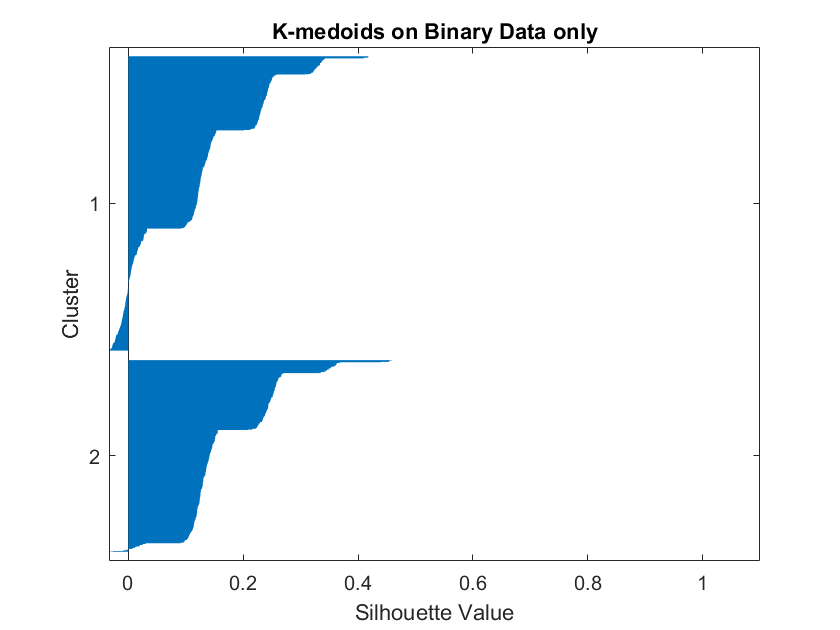

x1=X(:,[2,4:10,28]);
[idx,c]=kmedoids(x1,2,'Distance',"hamming");
figure()
silhouette(x1,idx)
title('K-medoids on Binary Data only')
figure()
% Visualize the clustering for say 
plot(x1(idx==1,5),x1(idx==1,8),'r.','MarkerSize',12)
hold on

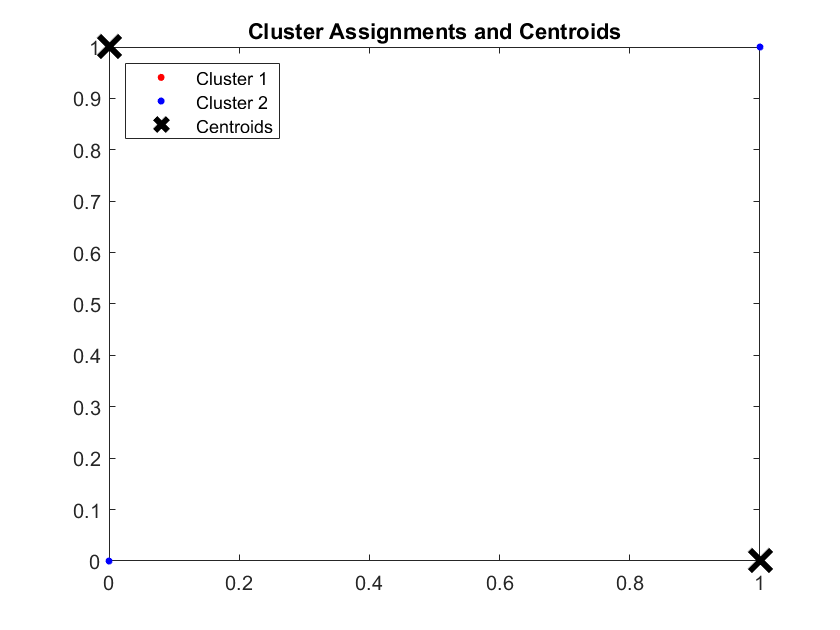

plot(x1(idx==2,5),x1(idx==2,8),'b.','MarkerSize',12)
plot(c(:,5),c(:,8),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

outp=Y+1;
[ac,pr,re]=meas(categorical(idx),outp);
m1=[ac,pr,re];

confusionmat(double(idx),double(outp))

K-means on continuous data only

x1=X(:,[1,3,11:27]);
[idx,c]=kmeans(x1,2);
silhouette(x1,idx)
title('K-means on continuous data only')

Class List in given sample
     1
     2


Total Instance = 1385
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1         398               441      
    Actual_class2         270               276      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [         398]    [          441]
    'TrueNegative=TN'    [         270]    [          276]

Over all valuses
                          Accuracy: 0.4866
                             Error: 0.5134
                       Sensitivity: 0.4744
                       Specificity: 0.5055
                         Precision: 0.5958
                 FalsePositiveRate: 0.4945
                          F1_score: 0.5282
    MatthewsCorrelationCoefficient: 0.0197
          

ans =    398   441
   270   276


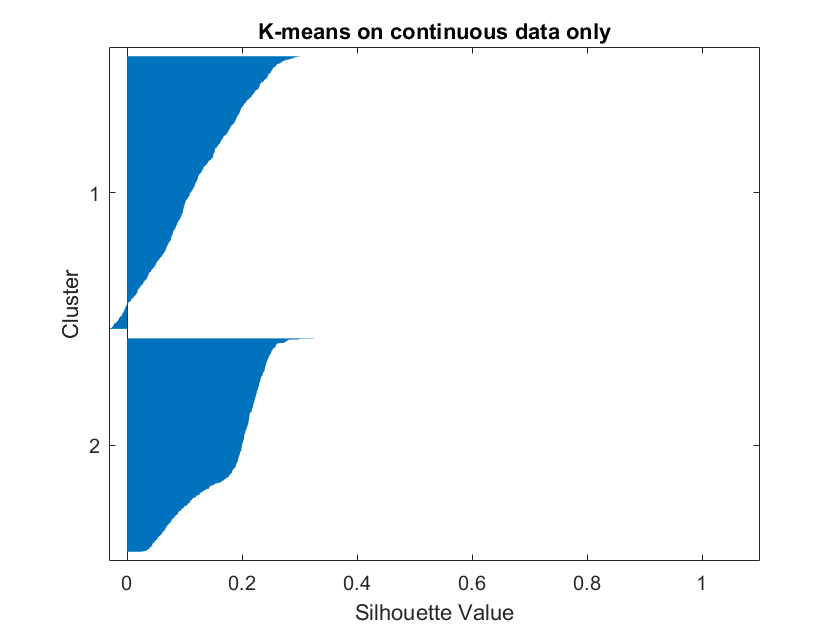


figure;
% Visualize the clustering for say 
plot(x1(idx==1,5),x1(idx==1,8),'r.','MarkerSize',12)
hold on

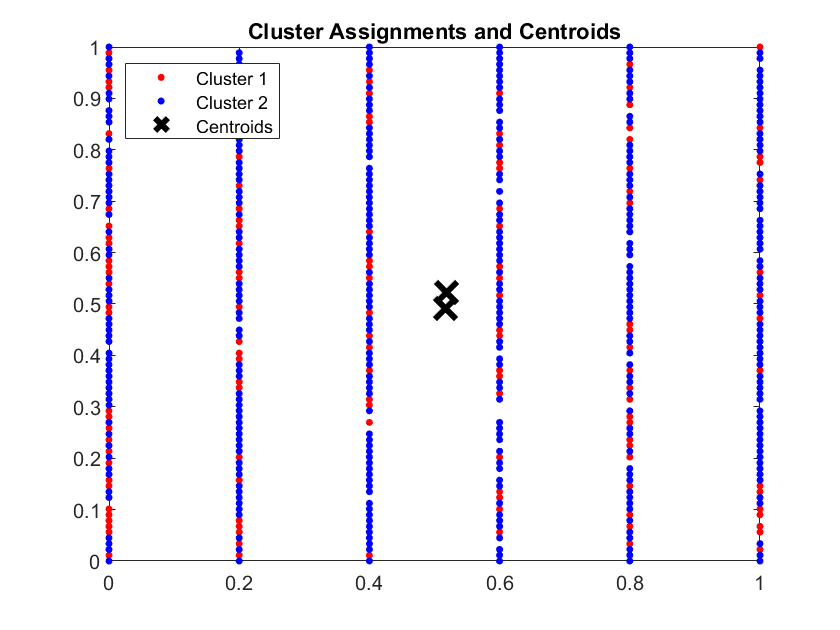

plot(x1(idx==2,5),x1(idx==2,8),'b.','MarkerSize',12)
plot(c(:,5),c(:,8),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

outp=Y+1;
[ac,pr,re]=meas(categorical(idx),outp);
m2=[ac,pr,re];
confusionmat(double(idx),double(outp))

K-means on entire data

[idx,c]=kmeans(X,2);
silhouette(X,idx)
title('K-means on entire data')


Class List in given sample
     1
     2


Total Instance = 1385
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1         366               411      
    Actual_class2         302               306      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [         366]    [          411]
    'TrueNegative=TN'    [         302]    [          306]

Over all valuses
                          Accuracy: 0.4852
                             Error: 0.5148
                       Sensitivity: 0.4710
                       Specificity: 0.5033
                         Precision: 0.5479
                 FalsePositiveRate: 0.4967
                          F1_score: 0.5066
    MatthewsCorrelationCoefficient: 0.0255
          

ans =    366   411
   302   306


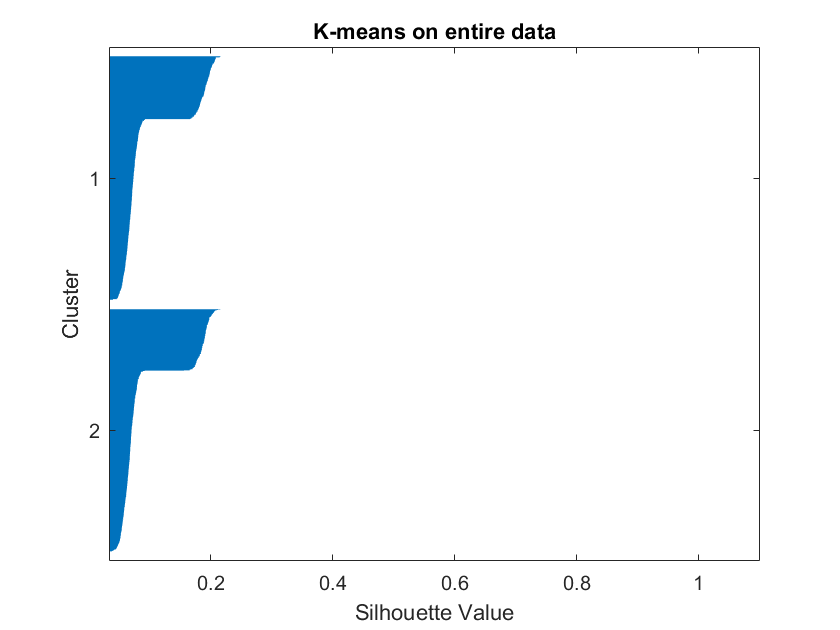

figure;
% Visualize the clustering for say 
plot(X(idx==1,5),X(idx==1,27),'r.','MarkerSize',12)
hold on

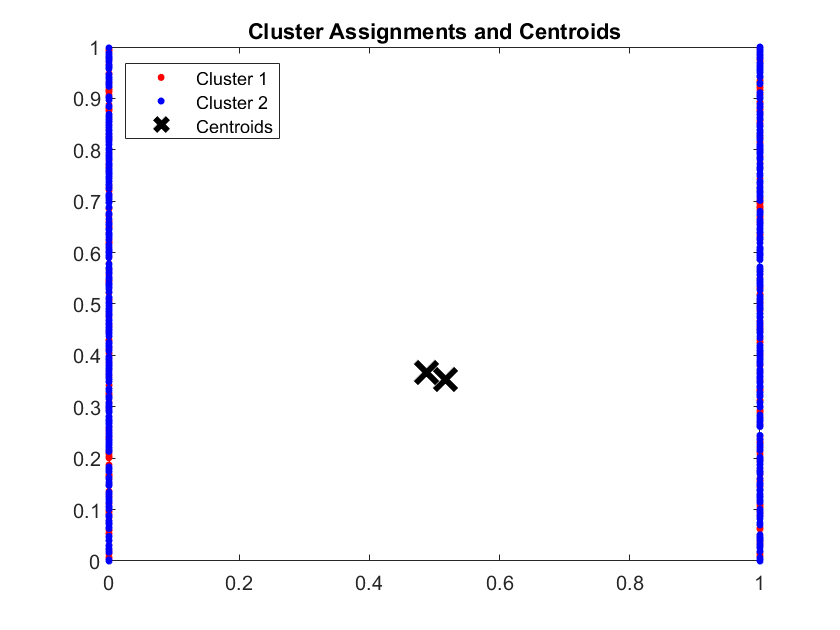

plot(X(idx==2,5),X(idx==2,27),'b.','MarkerSize',12)
plot(c(:,5),c(:,27),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

outp=Y+1;
[ac,pr,re]=meas(categorical(idx),outp);
m3=[ac,pr,re];
confusionmat(double(idx),double(outp))

K-medoids on entire data

[idx,c]=kmedoids(X,2);
silhouette(X,idx)
title('K-medoids on entire data')


Class List in given sample
     1
     2


Total Instance = 1385
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1         347               347      
    Actual_class2         321               370      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [         347]    [          347]
    'TrueNegative=TN'    [         321]    [          370]

Over all valuses
                          Accuracy: 0.5177
                             Error: 0.4823
                       Sensitivity: 0.5000
                       Specificity: 0.5355
                         Precision: 0.5195
                 FalsePositiveRate: 0.4645
                          F1_score: 0.5095
    MatthewsCorrelationCoefficient: 0.0355
          

ans =    347   347
   321   370


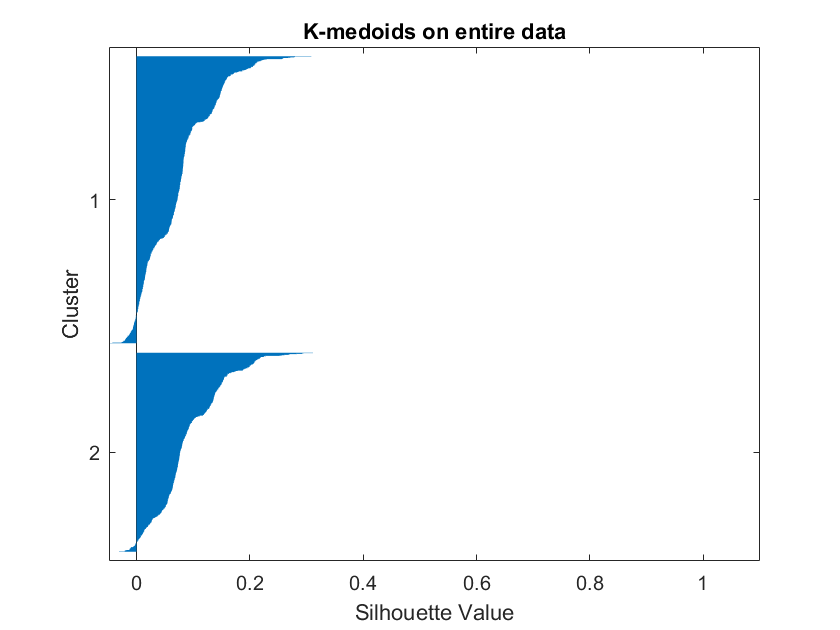

figure;
% Visualize the clustering for say 
plot(X(idx==1,5),X(idx==1,27),'r.','MarkerSize',12)
hold on

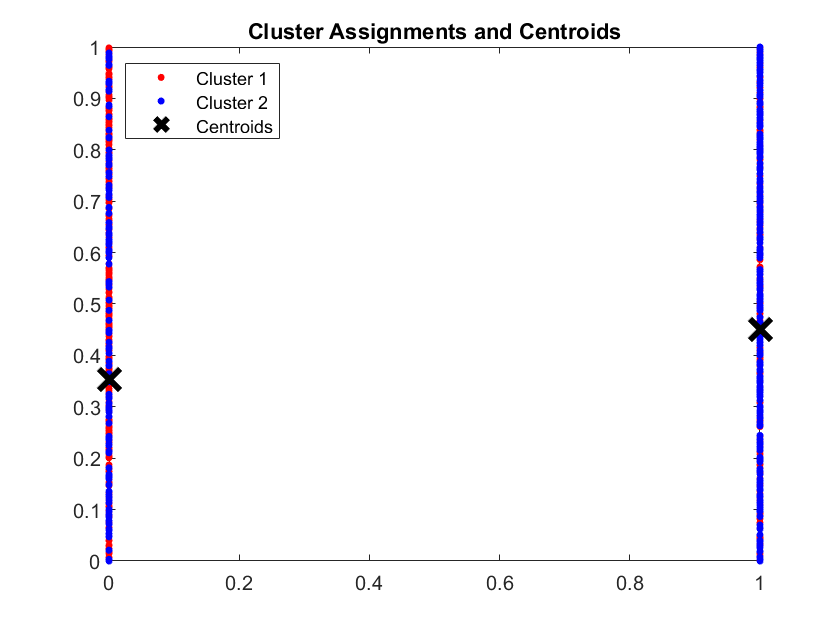

plot(X(idx==2,5),X(idx==2,27),'b.','MarkerSize',12)
plot(c(:,5),c(:,27),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

outp=Y+1;
[ac,pr,re]=meas(categorical(idx),outp);
m4=[ac,pr,re];
confusionmat(double(idx),double(outp))


array2table([m1;m2;m3;m4],'RowNames',{'K-medoids_Binary','K-means_Continuous','K-means_Entire','K-medoids_Entire'},...
    'VariableNames',{'Accuracy','Precision','Recall'})

## Compare FS Method models with Random Guess

% compare with 100 random predictions
for i = 1:250

Class List in given sample
     1
     2


Total Instance = 1385
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1         418               400      
    Actual_class2         250               317      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [         418]    [          400]
    'TrueNegative=TN'    [         250]    [          317]

Over all valuses
                          Accuracy: 0.5307
                             Error: 0.4693
                       Sensitivity: 0.5110
                       Specificity: 0.5591
                         Precision: 0.6257
                 FalsePositiveRate: 0.4409
                          F1_score: 0.5626
    MatthewsCorrelationCoefficient: 0.0690
          

ans =    418   400
   250   317


    random_pred = Ytrain1(randperm(length(Ytest1)));
    accuracy_guess(i,1) = sum(random_pred == Ytest1)/length(Ytest1);
    precision_guess(i,1) = sum(random_pred==1 & Ytest1==1)/sum(random_pred==1);

ans = 4×3 table
                          Accuracy    Precision    Recall 
                          ________    _________    _______

    K-medoids_Binary      0.48664      0.47437     0.59581
    K-means_Continuous     0.4852      0.47104      0.5479
    K-means_Entire        0.51769          0.5     0.51946
    K-medoids_Entire      0.53069        0.511     0.62575


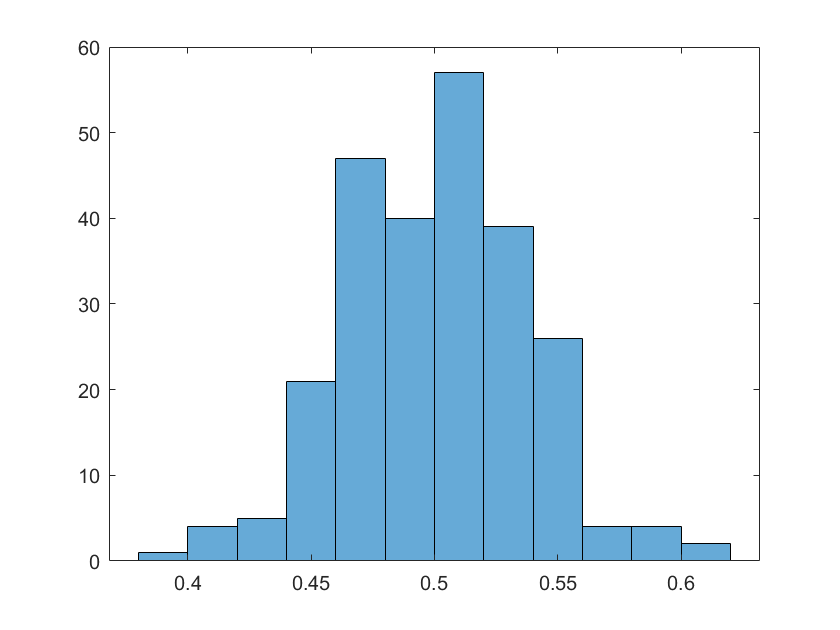

    recall_guess(i,1) = sum(random_pred==1 & Ytest1==1)/sum(Ytest1==1);
end
histogram(accuracy_guess)
% Naive bayes performed with TTest feature selection gives maximum accuracy
% (Supervised Learning)
[h_acc, p_acc] = ttest2(method1(4,1), accuracy_guess)
[h_pre, p_pre] = ttest2(method1(4,2), precision_guess)
[h_rec, p_rec] = ttest2(method1(4,3), recall_guess)
% K-medoids on entire data performed 
[h_acc, p_acc] = ttest2(m4(1,1), accuracy_guess)

[h_pre, p_pre] = ttest2(m4(1,2), precision_guess)
[h_rec, p_rec] = ttest2(m4(1,3), recall_guess)

function [acc,prec,rec]=meas(p,y)

h_acc = 0

p_acc = 0.5226

    acc=sum(p==categorical(y))/length(y);

h_pre = 0

p_pre = 0.3134

    p=double(p);

h_rec = 1

p_rec = 3.1421e-07

    prec=sum(p==1 & y==1)/sum(p==1);
    rec=sum(p==1 & y==1)/sum(y==1);

h_acc = 0

p_acc = 0.4669

end

h_pre = 0

p_pre = 0.9823

h_rec = 1

p_rec = 0.0170